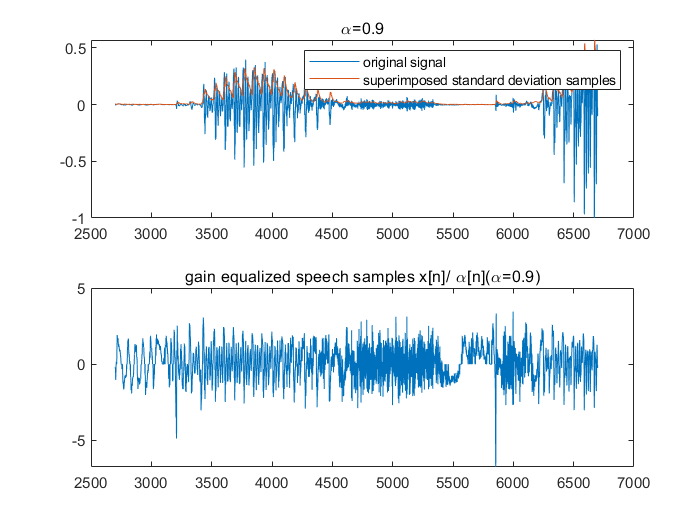

[s,fs]=audioread('s5.wav');
alpha_1=0.9;
alpha_2=0.99;
va1=zeros(1,length(s));
va2=zeros(1,length(s));
%IIR
for i=2:length(s)
    va1(i)=alpha_1*va1(i-1)+(1-alpha_1)*(s(i-1)^2);
    va2(i)=alpha_2*va2(i-1)+(1-alpha_2)*(s(i-1)^2);
end

va1_std=sqrt(va1);
va2_std=sqrt(va2);

figure
subplot(2,1,1);
plot(2700:1:6700,s(2700:6700));hold on
plot(2700:1:6700,va1_std(2700:6700));
title('\alpha=0.9');
legend('original signal','superimposed standard deviation samples');
subplot(2,1,2);
plot(2700:1:6700,(s(2700:6700))./(va1_std(2700:6700)'));
title('gain equalized speech samples x[n]/ \alpha[n](\alpha=0.9)');

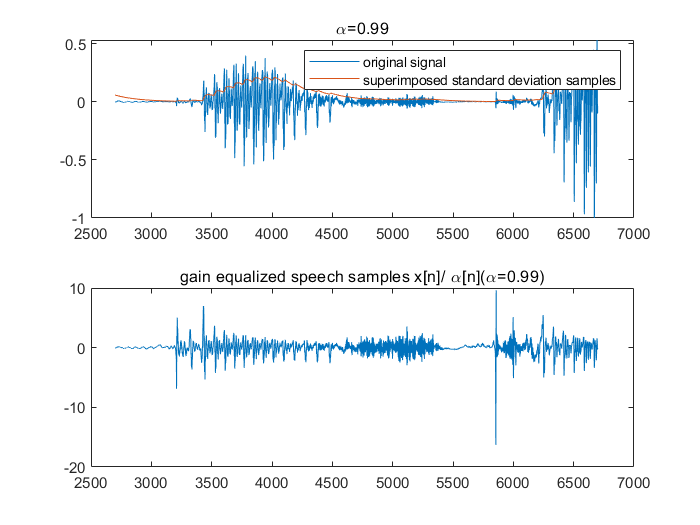


figure
subplot(2,1,1);
plot(2700:1:6700,s(2700:6700));hold on
plot(2700:1:6700,va2_std(2700:6700));
title('\alpha=0.99');
legend('original signal','superimposed standard deviation samples');
subplot(2,1,2);
plot(2700:1:6700,(s(2700:6700))./(va2_std(2700:6700)'));
title('gain equalized speech samples x[n]/ \alpha[n](\alpha=0.99)');

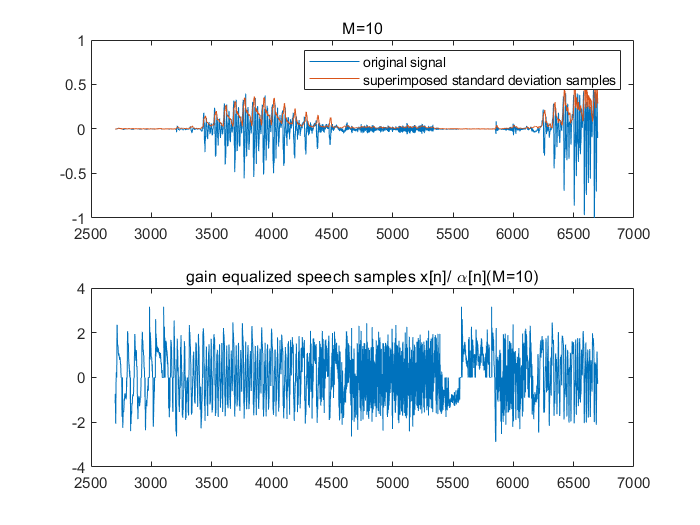


%FIR
va1_FIR=zeros(1,length(s));% M=10
va2_FIR=zeros(1,length(s));% M=100
M1=10;
M2=100;
for i=M1:length(s)
    va1_FIR(i)=1/M1*sum(s(i-M1+1:i).^2);    
end
for i=M2:length(s)
    va2_FIR(i)=1/M2*sum(s(i-M2+1:i).^2);    
end
va1_FIR_std=sqrt(va1_FIR);
va2_FIR_std=sqrt(va2_FIR);

figure
subplot(2,1,1);
plot(2700:1:6700,s(2700:6700));hold on
plot(2700:1:6700,va1_FIR_std(2700:6700));
title('M=10');
legend('original signal','superimposed standard deviation samples');
subplot(2,1,2);
plot(2700:1:6700,(s(2700:6700))./(va1_FIR_std(2700:6700)'));
title('gain equalized speech samples x[n]/ \alpha[n](M=10)');

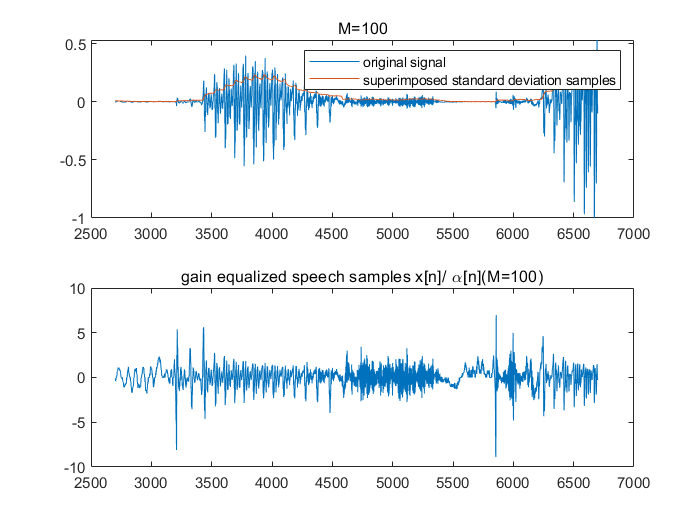


figure
subplot(2,1,1);
plot(2700:1:6700,s(2700:6700));hold on
plot(2700:1:6700,va2_FIR_std(2700:6700));
title('M=100');
legend('original signal','superimposed standard deviation samples');
subplot(2,1,2);
plot(2700:1:6700,(s(2700:6700))./(va2_FIR_std(2700:6700)'));
title('gain equalized speech samples x[n]/ \alpha[n](M=100)');